clc; clf
% 材料属性
CL = 6.35e3;
CT = 3.13e3;
h = 0.5e-3;
mu = 26e9;
lambda = 51e9;

INPUT：频率

f = 3e6;
cf = 2*pi*f; % 圆频率
w_sca = cf/CT*h; % 无量纲频率

Fun = @lamb;
[root,~,nmode] = get_wavenumber(w_sca,Fun); % 得到无量纲波数root
[Amp] = get_amplitudes( root,w_sca,Fun );

INPUT：模态阶数

mode = nmode+1 -5; % 模态阶数
A = Amp(:,mode);
kd = root(mode); wd = w_sca;

% 代入Amplitude，得到位移表达式
k = kd/h; w = wd*CT/h;
p = sqrt(w.^2/CL^2 - k.^2);
q = sqrt(w.^2/CT^2 - k.^2);

A = A/3e3; % 缩放
x = linspace(-h,h,1000)';

E = [exp(1i*p*x), exp(-1i*p*x), exp(1i*q*x), exp(-1i*q*x)];
U = E * diag([k*[1 1], q*[-1 1]].*1i) * A ;
V = E * diag([p*[1 -1], k*[1 1]].*1i) * A;
u = imag(U);
v = real(V);

## 振型图

 
u = -u; v = -v;

 
v = -v;

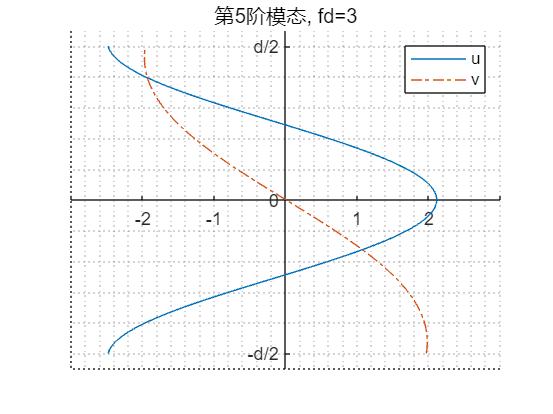

 
f1 = figure;
hold on
plot(u,x,'-')
plot(v,x,'-.')
hold off

ax1 = gca;
set(ax1,'XAxisLocation','origin','YAxisLocation','origin','YTick',[-h,0,h], ...
	'yticklabels',{'-d/2','0','d/2'},'YLim',[-1.1*h,1.1*h])
title(['第',num2str(nmode+1-mode),'阶模态, fd=' num2str(2*f*h/1e3)]); 
legend('u','v'); grid minor